# EKF tuning with Bayesian Optimization

clc
clf
clear all
close all
rng(0)

## Parallel computing

if isempty(gcp('nocreate'))
    cluster = parcluster('local');
    parpool(cluster, cluster.NumWorkers);
end
p = gcp();
fprintf('Using %d parallel workers', p.NumWorkers);

Using 8 parallel workers

## Define optimization variables

qi = optimizableVariable('qi', [1e-12, 1e3], 'Transform', 'log');
qF = optimizableVariable('qF', [1e-12, 1e3], 'Transform', 'log');
qw = optimizableVariable('qw', [1e-12, 1e3], 'Transform', 'log');

optimization_variables = [qi, qF, qw];
nVars = size(optimization_variables, 2);

## Objective function

Simulate MMCC + Induction Machine and calculate MPC mean cost

function cost = objective_function(x)
    try
        cost = KF_simulate(x);
    catch
        cost = 10;
    end
end

## Bayesian optimization

Copying objective function to workers...
Done copying objective function to workers.
|==============================================================================================================================|
| Iter | Active  | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |           qi |           qF |           qw |
|      | workers | result |             | runtime     | (observed)  | (estim.)    |              |              |              |
|==============================================================================================================================|
|    1 |       1 | Accept |  1.1856e+05 |      2.7253 |       2.401 |      2.3956 |   1.1449e-05 |   1.2005e-09 |   9.7625e-06 |
|    2 |       1 | Accept |      178.84 |      2.9641 |       2.401 |      2.3956 |       1.9078 |   8.8726e-09 |   2.5314e-11 |
|    3 |       1 | Accept |      6554.6 |      2.7569 |       2.401 |      2.3956 |      0.14395 |   4.4364e-09 |   3.1748e-10 |
|    4 |    

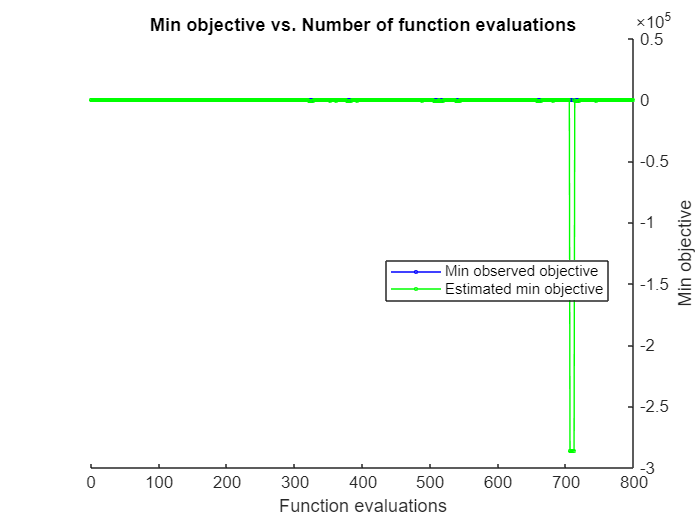

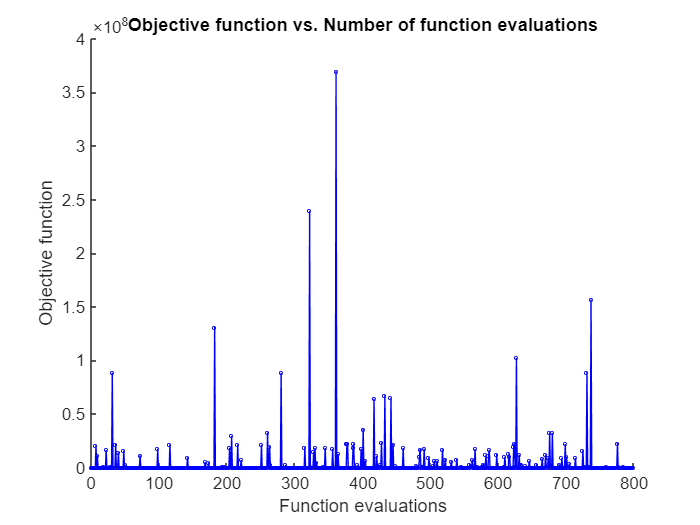

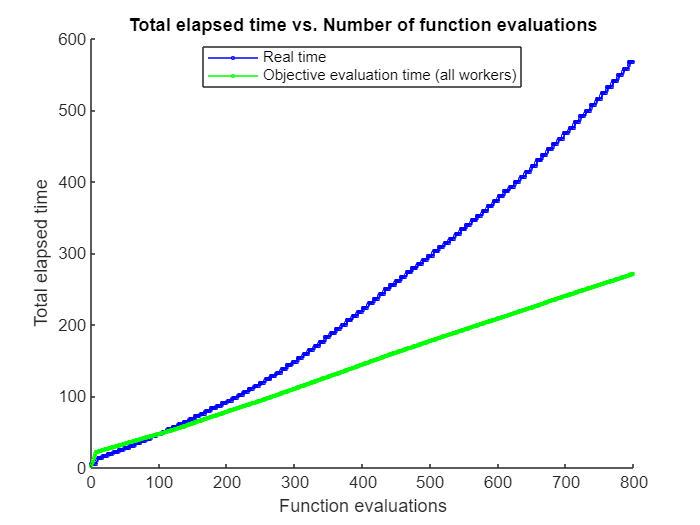

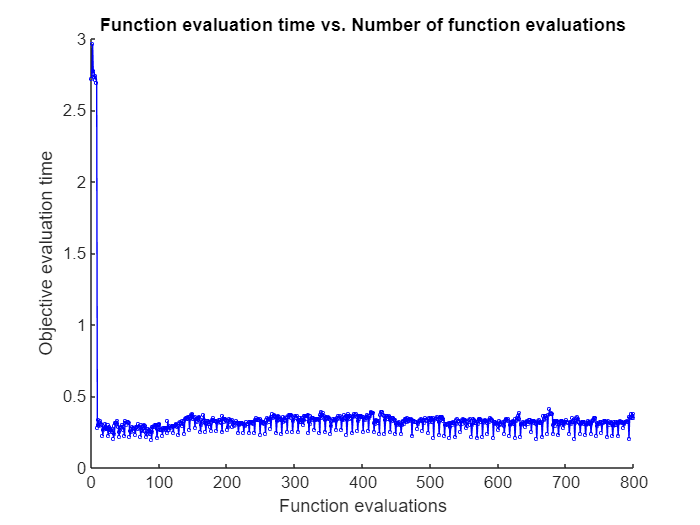

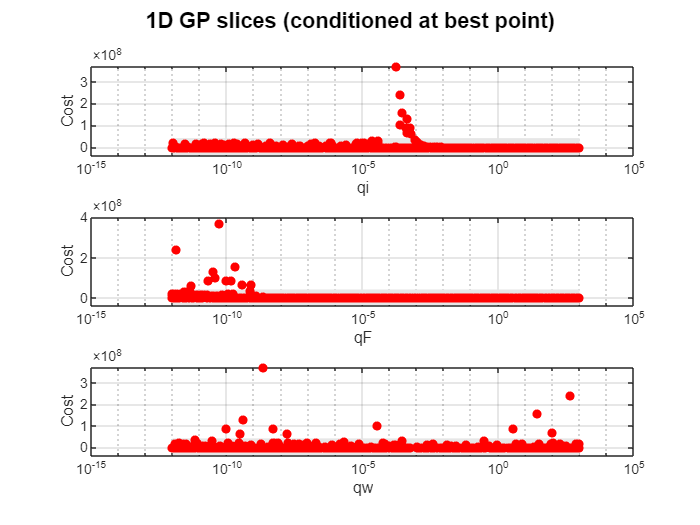

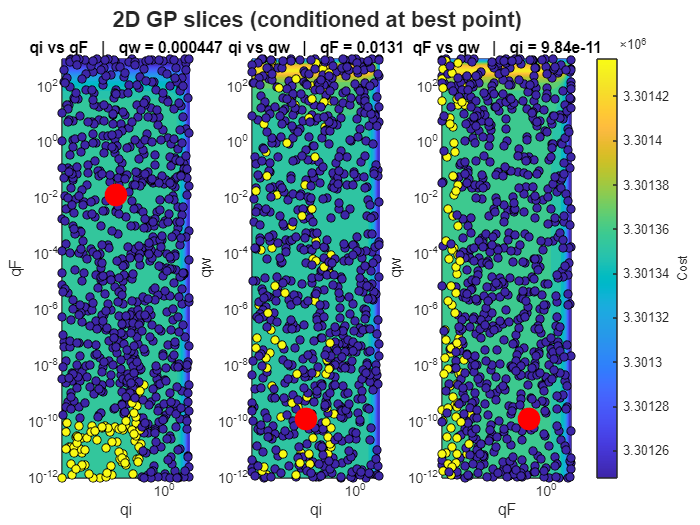


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 800 reached.
Total function evaluations: 800
Total elapsed time: 567.7578 seconds
Total objective function evaluation time: 271.9205

Best observed feasible point:
        qi           qF           qw    
    __________    ________    __________
    2.4899e-06    0.014243    1.3321e-10
Observed objective function value = 1.9359
Estimated objective function value = 1.9449
Function evaluation time = 0.36376

Best estimated feasible point (according to models):
        qi           qF           qw    
    __________    ________    __________
    9.8449e-11    0.013052    0.00044656
Estimated objective function value = 1.9377
Estimated function evaluation time = 0.32508



bnds = vertcat(optimization_variables.Range);
lb = log10(bnds(:,1).');
ub = log10(bnds(:,2).');

NumSeedPoints = 10*p.NumWorkers;
Xlhs = lhsdesign(NumSeedPoints, nVars);
Xinit = 10 .^ bsxfun(@plus, lb, bsxfun(@times, (ub-lb), Xlhs));
Xinit = array2table(Xinit, 'VariableNames', {optimization_variables.Name});

results = bayesopt(@objective_function, optimization_variables, ...
    'MaxObjectiveEvaluations',   100*p.NumWorkers, ...
    'InitialX',                  Xinit, ...
    'AcquisitionFunctionName',   'expected-improvement-plus', ...
    'IsObjectiveDeterministic',  true, ...
    'UseParallel',               true, ...
    'Verbose',                   1, ...
    'PlotFcn',                   {@plotMinObjective, ...
                                  @plotObjective, ...
                                  @plotElapsedTime, ...
                                  @plotObjectiveEvaluationTime, ...
                                  @plotSurrogate} ...
);

## Reconstruct GP model

Retrieve bayesian optimization results

X = results.XTrace;
Y = results.ObjectiveTrace;
[Y, idx] = sort(Y, 'ascend'); % Sort by cost function
X = X(idx, :); 
varNames = {results.VariableDescriptions.Name};
sorted_Trace = [X table(Y, 'VariableNames', {'Cost'})]

sorted_Trace = 800×4 table
        qi           qF            qw         Cost 
    __________    _________    __________    ______
    2.4899e-06     0.014243    1.3321e-10    1.9359
    9.8449e-11     0.013052    0.00044656    1.9359
     4.723e-11      0.01001    1.3297e-06    1.9414
    3.7154e-06     0.018321     1.467e-10    1.9477
    2.4344e-10      0.02109    7.1308e-10     1.956
    3.8564e-10    0.0076118    8.3107e-07    1.9695
    1.1821e-11     0.024126    5.2497e-11    1.9696
    2.8673e-06    0.0070674    1.3629e-10    1.9751
    9.9321e-10     0.030453    1.5545e-05    1.9976
    5.7901e-06     0.030501    4.5878e-09    2.0056
    4.3971e-06    0.0055566    2.1728e-06    2.0154
    0.00015381    0.0084465    1.2847e-12    2.0616
    8.1189e-06     0.019643        953.66     2.062
     4.679e-12     0.010794       0.07352    2.0909
    1

Fit gaussian process

gp = fitrgp(X, Y, ...
    'Standardize', true, ...
    'KernelFunction', 'ardsquaredexponential');

## Plot GP

Plot fitted gaussian process

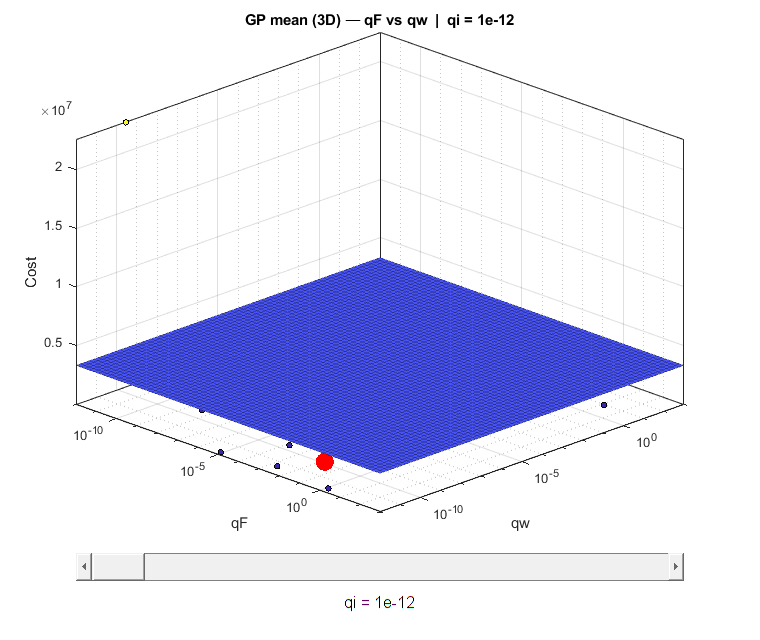

plotGP(gp, results, 'qF', 'qw')

## Sensitivity analysis

Global (trained kernel length scales)

lengthScales = gpGlobalSensitivity(gp)

lengthScales =     2.7834    2.5464    0.9781


Local (model gradient)

x_eval = table2array(X(1, :));
[gradMu, gradSigma2] = gpLocalSensitivity(gp, x_eval)

gradMu =   -14.6708  -14.4183  -11.6909


gradSigma2 = 1.0e+03 *

   -1.6147   -1.2704   -3.5785
